% =========================================================================
% FSUK EV Accumulator & Motor Current Sizing Script
% Based on: Molicel P30B (28s22p) & 100V DC Motor Datasheet
% =========================================================================

clc; clear; close all;

%% 1. Cell Data (Molicel P30B 18650)
cell_V_nom = 3.6;       % [V] Nominal cell voltage
cell_V_max = 4.2;       % [V] Max cell voltage
cell_V_min = 2.8;       % [V] Assumed min/cutoff cell voltage
cell_cap_Ah = 3.0;      % [Ah] Cell capacity
cell_mass_kg = 0.048;   % [kg] Cell mass (48g)

%% 2. Accumulator Configuration
Ns = 28;                % Number of cells in series
Np = 22;                % Number of cells in parallel
num_segments = 4;       % Number of segments in series

% Derived Segment Configuration
Ns_per_segment = Ns / num_segments; % 7

%% 3. Accumulator Level Calculations
total_cells = Ns * Np;
accu_V_nom = Ns * cell_V_nom;
accu_V_max = Ns * cell_V_max;
accu_V_min = Ns * cell_V_min;
accu_cap_Ah = Np * cell_cap_Ah;


% Energy calculations
accu_energy_Wh = accu_V_nom * accu_cap_Ah;
accu_energy_kWh = accu_energy_Wh / 1000;


% Mass calculations
accu_cell_mass_kg = total_cells * cell_mass_kg;

%% 4. Segment Level Calculations & FSUK Rule Checks
cells_per_segment = total_cells / num_segments;
segment_V_max = Ns_per_segment * cell_V_max;
segment_V_nom = Ns_per_segment * cell_V_nom;

segment_energy_Wh = accu_energy_Wh / num_segments;
segment_energy_kWh = segment_energy_Wh / 1000;
% 1 Wh = 3600 Joules
segment_energy_MJ = (segment_energy_Wh * 3600) / 1e6; 

segment_cell_mass_kg = accu_cell_mass_kg / num_segments;
fsuk_segment_mass_limit = 12.0; % [kg]
segment_mass_margin = fsuk_segment_mass_limit - segment_cell_mass_kg;


%% 5. Motor Data & Current Draw Calculations
motor_P_cont_kW = 22.5;     % [kW] Continuous Power
motor_P_peak_kW = 48.0;     % [kW] Peak Power
motor_eff_max = 0.92;       % Maximum efficiency (92%)

% Calculate Required DC Current (Inverter Input)
% P_elec = P_mech / efficiency
% I_dc = P_elec / V_accu

% Current at Continuous Power (22.5 kW)
I_cont_nomV = (motor_P_cont_kW * 1000 / motor_eff_max) / accu_V_nom;

% Current at Peak Power (48.0 kW)
I_peak_nomV = (motor_P_peak_kW * 1000 / motor_eff_max) / accu_V_nom;
I_peak_minV = (motor_P_peak_kW * 1000 / motor_eff_max) / accu_V_min;

%% 6. Display Results to Command Window
fprintf('====================================================\n');

fprintf('          ACCUMULATOR ELECTRICAL SPECS              \n');

          ACCUMULATOR ELECTRICAL SPECS              


fprintf('====================================================\n');

fprintf('Configuration:           %ds%dp (%d cells total)\n', Ns, Np, total_cells);

Configuration:           28s22p (616 cells total)


fprintf('Nominal Voltage:         %.1f V\n', accu_V_nom);

Nominal Voltage:         100.8 V


fprintf('Maximum Voltage:         %.1f V\n', accu_V_max);

Maximum Voltage:         117.6 V


fprintf('Accumulator Capacity:    %.1f Ah\n', accu_cap_Ah);

Accumulator Capacity:    66.0 Ah


fprintf('Total Energy:            %.2f kWh\n', accu_energy_kWh);

Total Energy:            6.65 kWh


fprintf('Total Cell Mass:         %.2f kg\n\n', accu_cell_mass_kg);

Total Cell Mass:         29.57 kg




fprintf('====================================================\n');

fprintf('             SEGMENT-LEVEL SPECS & RULES            \n');

             SEGMENT-LEVEL SPECS & RULES            


fprintf('====================================================\n');

fprintf('Number of Segments:      %d\n', num_segments);

Number of Segments:      4


fprintf('Segment Configuration:   %ds%dp (%d cells/segment)\n', Ns_per_segment, Np, cells_per_segment);

Segment Configuration:   7s22p (154 cells/segment)


fprintf('Max Segment Voltage:     %.1f V    (Limit: <= 120V) -> ', segment_V_max);

Max Segment Voltage:     29.4 V    (Limit: <= 120V) -> 

if segment_V_max <= 120, fprintf('PASS\n'); else, fprintf('FAIL\n'); end

PASS


fprintf('Segment Energy:          %.2f MJ  (Limit: <= 6 MJ)   -> ', segment_energy_MJ);

Segment Energy:          5.99 MJ  (Limit: <= 6 MJ)   -> 

if segment_energy_MJ <= 6, fprintf('PASS\n'); else, fprintf('FAIL\n'); end

PASS


fprintf('Segment Cell Mass:       %.2f kg\n', segment_cell_mass_kg);

Segment Cell Mass:       7.39 kg


fprintf('Remaining Mass allowed:  %.2f kg  (Limit: 12kg total)\n\n', segment_mass_margin);

Remaining Mass allowed:  4.61 kg  (Limit: 12kg total)




fprintf('====================================================\n');

fprintf('             MOTOR CURRENT DRAW MATCHING            \n');

             MOTOR CURRENT DRAW MATCHING            


fprintf('====================================================\n');

fprintf('Assumed Motor Efficiency: %.0f%%\n', motor_eff_max * 100);

Assumed Motor Efficiency: 92%


fprintf('Drawn Current @ Continuous Power (%.1f kW, %.1f V): %.1f A\n', motor_P_cont_kW, accu_V_nom, I_cont_nomV);

Drawn Current @ Continuous Power (22.5 kW, 100.8 V): 242.6 A


fprintf('Drawn Current @ Peak Power (%.1f kW, %.1f V):       %.1f A\n', motor_P_peak_kW, accu_V_nom, I_peak_nomV);

Drawn Current @ Peak Power (48.0 kW, 100.8 V):       517.6 A


fprintf('Drawn Current @ Peak Power (Worst Case %.1f V):      %.1f A\n', accu_V_min, I_peak_minV);

Drawn Current @ Peak Power (Worst Case 78.4 V):      665.5 A


fprintf('====================================================\n');


%% 7. Plotting Current Draw vs Required Motor Power
P_mech_req_kW_array = linspace(0, motor_P_peak_kW, 200);
P_elec_req_kW_array = P_mech_req_kW_array / motor_eff_max;

% Current arrays
I_draw_nom_array = (P_elec_req_kW_array * 1000) ./ accu_V_nom;
I_draw_min_array = (P_elec_req_kW_array * 1000) ./ accu_V_min;

figure('Name', 'Motor Current Draw vs Mechanical Power', 'Color', 'w');
plot(P_mech_req_kW_array, I_draw_nom_array, 'b-', 'LineWidth', 2);
hold on; grid on;
plot(P_mech_req_kW_array, I_draw_min_array, 'r--', 'LineWidth', 2);

% Mark Continuous and Peak operating points
plot(motor_P_cont_kW, I_cont_nomV, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
plot(motor_P_peak_kW, I_peak_nomV, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
plot(motor_P_peak_kW, I_peak_minV, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');


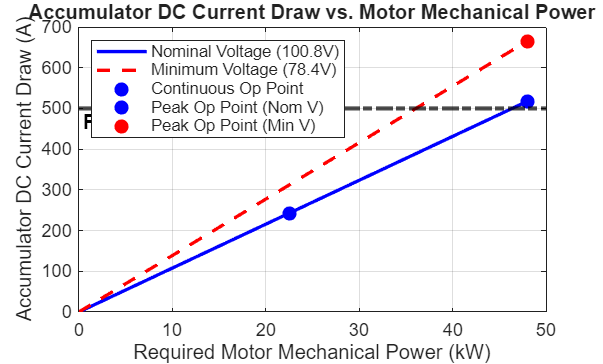

% Mark FSUK 500A Current Limit
fsuk_max_current_A = 500;
yline(fsuk_max_current_A, 'k-.', 'FSUK Limit (500A)', 'LineWidth', 2.5, ...
    'FontSize', 12, 'FontWeight', 'bold', 'LabelHorizontalAlignment', 'left', ...
    'LabelVerticalAlignment', 'bottom');

title('Accumulator DC Current Draw vs. Motor Mechanical Power');
xlabel('Required Motor Mechanical Power (kW)');
ylabel('Accumulator DC Current Draw (A)');
legend(sprintf('Nominal Voltage (%.1fV)', accu_V_nom), ...
       sprintf('Minimum Voltage (%.1fV)', accu_V_min), ...
       'Continuous Op Point', 'Peak Op Point (Nom V)', 'Peak Op Point (Min V)', ...
       'Location', 'northwest');
set(gca, 'FontSize', 11);